addpath("helperFunctions/");
clearvars;

# Monopole Wave

### Initial Parameters

n = 3; spacing = 0.01;
f = 200; c = 343; omega = 2*pi*f;
rho_k = omega/c;
S = [2;2;0];
[rho_s,the_s,phi_s] = my_cart2sph(S);
rx = -n:spacing:n;
ry = rx;
sz = [length(ry) length(rx)];
rz = zeros(size(rx));
r = [rx;ry;rz];
R = 0.5; % region of interrest
L = ceil(exp(1)*rho_k*R/2);

## Monopole Sound Source

figure;
wave = monopoleWave(S,r,rho_k,1);

## Harmonic Coefficients - Numerical Approximation


$$C_{lm}(k) = \frac{1}{\mathbf j_l(kr)}\int_0^\pi\int_0^{2\pi}P(r,\theta,\phi,k)\overline\mathbf{Y}_{lm}(\theta,\phi)d\theta d\phi$$


### Matlab

n = 1000;
a1 = 0;  a2 = 0;
b1 = pi; b2 = 2*pi;
Clm2 = zeros(L+1,2*L+1);


for l=0:L
    idl = l+1;
    for m=-l:l
        idm = m+idl;
        fun = @(the,phi) monopoleWaveSpherical(rho_s,the_s,phi_s,R,the,phi,rho_k).*cYlm(l,m,the,phi)./sphbessel(l,rho_k*R);
        Clm2(idl,idm) = integral2(fun,a1,b1,a2,b2);
    end
end

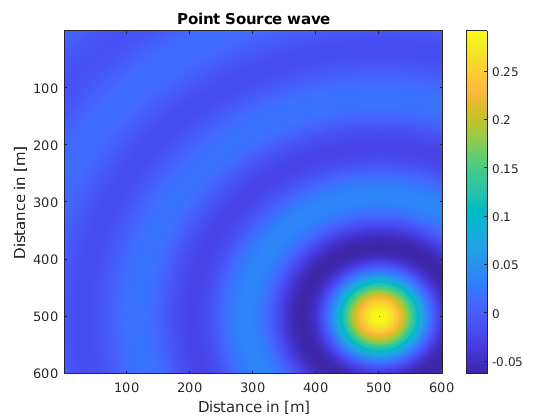

P2 = harmonics2pressure(Clm2,rho_k,r,sz);

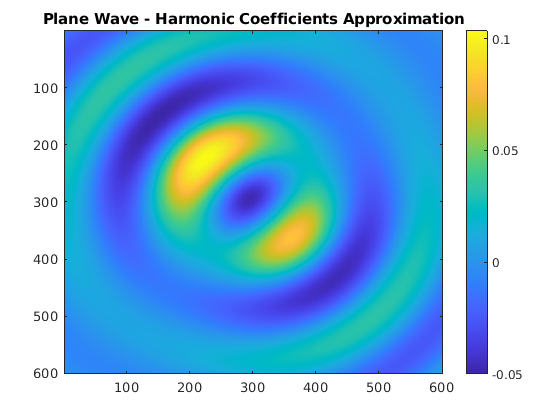

figure;
imagesc(imag(P2));
title("Plane Wave - Harmonic Coefficients Approximation");
colorbar;

### Compare

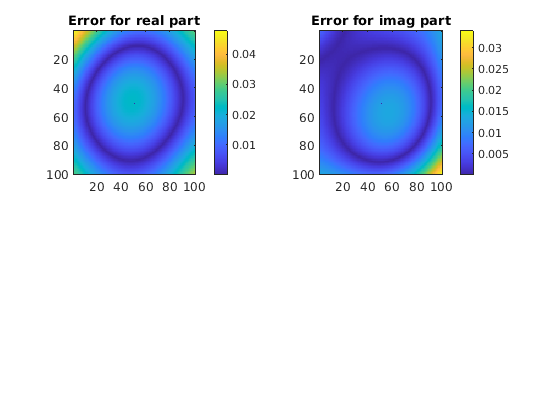

ans = "Max real error:  3.39e-02"

ans = "Max imag error:  4.77e-02"

ans = "Mean error: 8.24e-03"

interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);
cmpWaves(wave(interval1,interval2),P2(interval1,interval1),1);

### Guassian Sampling

N = L-1;
waveFun = @(R,the,phi) monopoleWaveSpherical(rho_s,the_s,phi_s,R,the,phi,rho_k);
Clm = harmonicCoefficients(L,R,rho_k,N,waveFun,n,wave,1);

### Evaluate

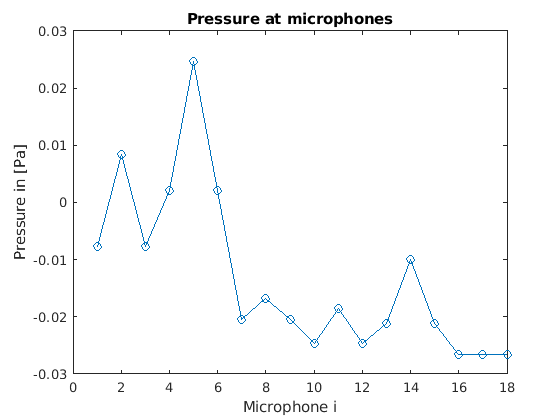

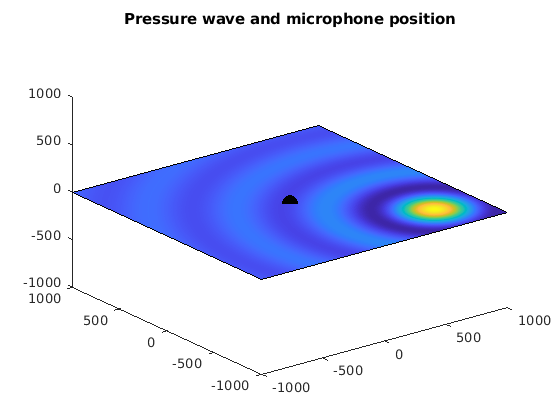

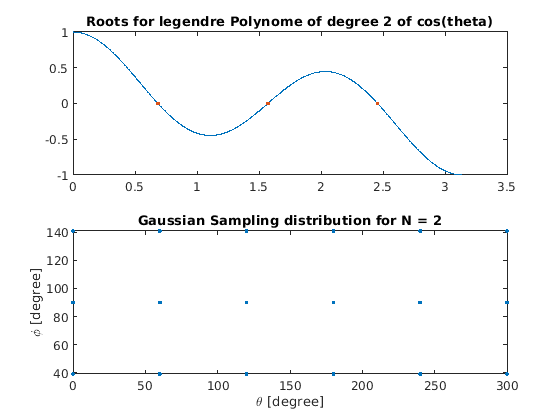

P = harmonics2pressure(Clm,rho_k,r,sz);

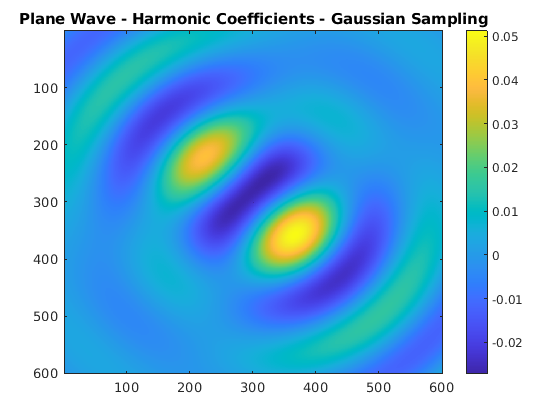

figure;
imagesc(imag(P));
title("Plane Wave - Harmonic Coefficients - Gaussian Sampling");
colorbar;

### Compare

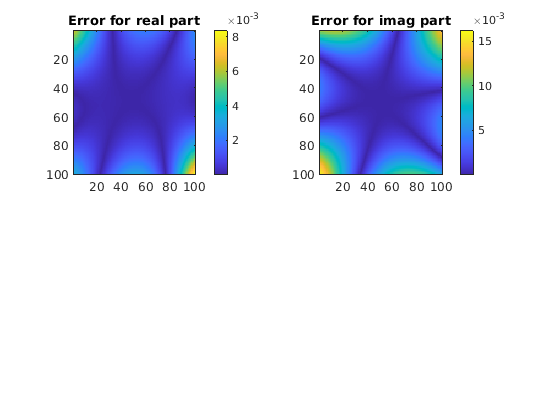

ans = "Max real error:  1.61e-02"

ans = "Max imag error:  8.33e-03"

ans = "Mean error: 1.82e-03"

interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);

cmpWaves(wave(interval1,interval2),P(interval1,interval1),1);